% mikexcohen.com

## load in EEG data and pick and electrode, trial, etc.

load sampleEEGdata.mat

chan2use  = 'fz';
trial2use = 34;

% extract this bit of data for convenience in the rest of this script
data = squeeze(EEG.data( strcmpi(chan2use,{EEG.chanlocs.labels}), :,trial2use));

## create a Morlet wavelet

srate = EEG.srate; % in hz
time  = -2:1/srate:2; % best practice is to have time=0 at the center of the wavelet
frex  = 6.5; % frequency of wavelet, in Hz

% create complex sine wave
sine_wave = exp(1i*2*pi*frex.*time);

% create Gaussian window
s = 7 / (2*pi*frex); % this is the standard deviation of the gaussian
gaus_win  = exp( (-time.^2) ./ (2*s^2) );

% now create Morlet wavelet
cmw  = sine_wave .* gaus_win;

## define convolution parameters

nData = length(data);
nKern = length(cmw);
nConv = nData + nKern - 1;

## FFTs

% note that the "N" parameter is the length of convolution, NOT the length
% of the original signals! Super-important!


% FFT of wavelet, and amplitude-normalize in the frequency domain
cmwX = fft(cmw,nConv);
cmwX = cmwX ./ max(cmwX); % ensure that result of cov. is in the same unit as orignal data


% FFT of data
dataX = fft(data,nConv);



% now for convolution...
conv_res = dataX .* cmwX;


% compute hz for plotting
hz = linspace(0,srate/2,floor(nConv/2)+1);

## some plots...

figure(1), clf

% plot power spectrum of data
subplot(311)
plot(hz,2*abs(dataX(1:length(hz))/length(data)))
set(gca,'xlim',[0 30])

% plot power spectrum of wavelet
subplot(312)
plot(hz,abs(cmwX(1:length(hz))))
set(gca,'xlim',[0 30])

% plot power spectrum of convolution result
subplot(313)
plot(hz,2*abs(conv_res(1:length(hz))/length(data)))
set(gca,'xlim',[0 30])

## now back to the time domain

length(conv_res)

ans = 1664

EEG.pnts

ans = 640

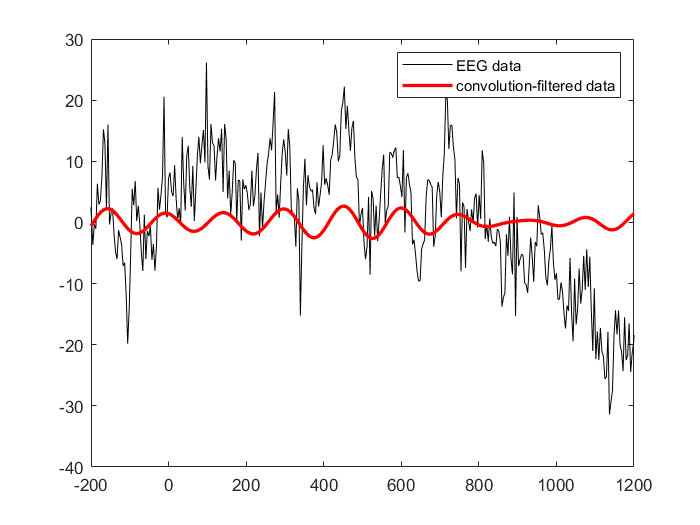


% cut 1/2 of the length of the wavelet from the beginning and from the end
half_wav = floor( length(cmw)/2 )+1;

% take inverse Fourier transform
conv_res_timedomain = ifft(conv_res);

conv_res_timedomain = conv_res_timedomain(half_wav-1:end-half_wav);

figure(2), clf
plot(EEG.times,data,'k')
hold on
plot(EEG.times,real(conv_res_timedomain),'r','linew',2)
set(gca,'xlim',[-200 1200])
legend({'EEG data';'convolution-filtered data'})